Math 131: Coding Exam 2

Munoz, Alexander

Chosen Exercise: Composite Trapezoid Rule: Part C

Exercise Data:

f = @(x)(cos(2*x)+x);%given function cos(2x)+x
%accuracy is set to 10^-4
acc = 10.^(-4);
%call the function with the given values:
%bounds from 1 to 4 with an accuracy of 10^-4
comp1 = composite_trapezoid(f, 1, 4, acc)

comp1 = 6.6575e+04

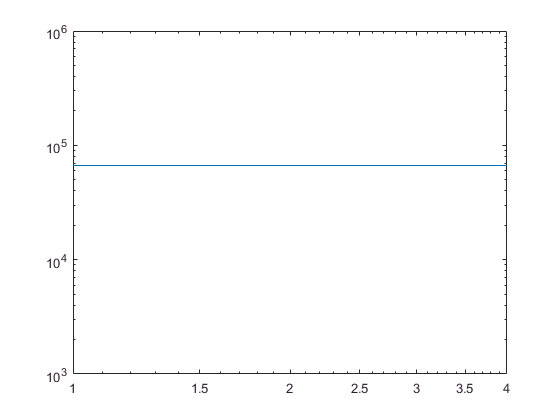

%exact = fresnelc(8) used to solve for the exact value

%will solve for the absolute error o
%error = abs(exact - comp1)/exact
x = [1, 4];
y = [comp1, comp1];
loglog(x, y)

The solved composite trapezoid with the given values is 6.6575 * 10^4

What is the order of the error for this method?

    Using the Composite Trapezoid Rule, error is: O(h^2).

function J = composite_trapezoid(f, a, b, n)
%the function will approximate the integral by using a series of
%trapezoids from bounds a to b
    J = 0;
    %h is used to solve for the size of each trapezoid width
    h = (b-a)/n;
    %sets the bounds for x
    x = [a+h:h:b-h];
    for i = 1: n-1
        J = J + f(x(i));
    end
    %general function for (f(a) + f(b))/2 for a trapezoid with width 'h'
    J = h * (J + 0.5*(f(a)+f(b)));
end